clear; clc; close all

iyear = 2011;
imonth = 9;
iday = 10;
ibasin = 9; % Baltic = 9

[xmin,xmax,ymin,ymax,basin_str] = map_lim_raf (ibasin);

% ========================
path_root = ('/Volumes/Rogue/Data/');
folder_data = ([path_root ...
    'SSS/Baltic/BEC/Validation/model/']);

% create a storage folder
folder_figs = ['/Volumes/Rogue/scratch/Validation/' basin_str '/NEMO/'];

fg_save = 1; % flag save figures [1]; or not [0];
fg_format = 'png';


[data_model] = Baltic_model_BEC_analyses_FUN (iyear,imonth,iday,ibasin);

tt = data_model;

SSS_model = tt.SSS_model;
SST_model = tt.SST_model;
MLD_model = tt.MLD_model;
TIME_model = tt.TIME_model;
lon = tt.lon;
lat = tt.lat;

clear tt

## Plot NEMO monthly MAPS

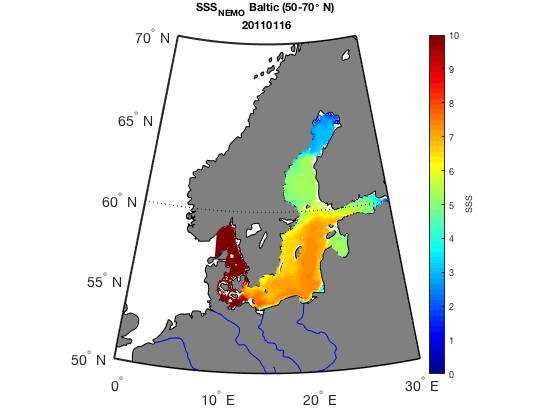

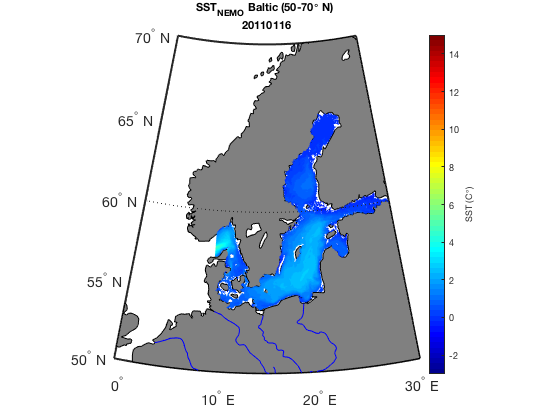

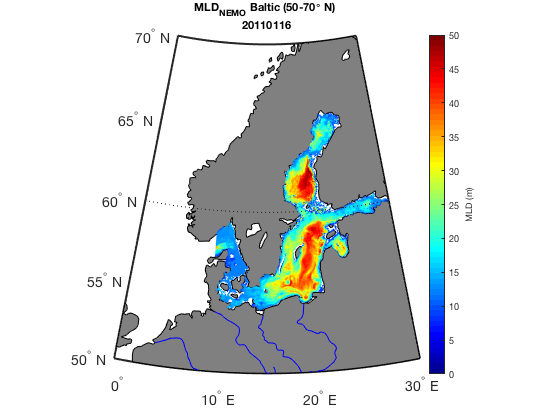

lat_min = ymin;
lat_max = ymax;
lon_min = xmin;
lon_max = xmax;

% Make surface plots of all variables in the model (iparam_str_all) and for
% all TIME_model available
iparam_str_all = {'SSS','SST','MLD'};

for pp = 1:length(iparam_str_all) % loop through variables
    for tt = 1:length(TIME_model)  % loop through time
        %
        iparam_str = iparam_str_all{pp};
        itime_num = TIME_model(tt);
        
        eval(['param_in = squeeze(' iparam_str '_model(:,:,' num2str(tt) '));'])
        
        % funcion-snipet to plot baltic model data
        figure
        [h1,fg_name] = plot_map_model_BEC(lon,lat,param_in,iparam_str,ibasin,itime_num);
        
        title({[iparam_str '_{NEMO} ' basin_str ' ('...
            num2str(lat_min) '-' ...
            num2str(lat_max) '\circ N) ' ]; ...
            [datestr(itime_num,'yyyymmdd')]});
        
        % Save figure  - output -
        folder_this = [folder_figs 'MAPS/' iparam_str '/'];
        
        if fg_save == 1
            foldercheck_raf(folder_this); %! make folder_figs
        end
        
        fg_name = [folder_this fg_name '.' fg_format];
        
        % check fn existence
        fg_exist = exist(fg_name,'file');
        if fg_save == 1 && fg_exist == 0
            save_raf(gcf,fg_name,fg_format); close
        end
    end
end




%%

plot(TIME_model,SSS_model)

Error using plot
Vectors must be the same length.